## 1. 编写函数实现基于回溯法的最速下降法，以Rosenbrock函数作为目标函数进行测试：

clf;
clc;
x0 = [-1.2; 1.2];
tic
[x, fx, count] = SteepestDescent(@Rosenbrock, @BackTracking, x0, 1e5);
toc

时间已过 0.990816 秒。


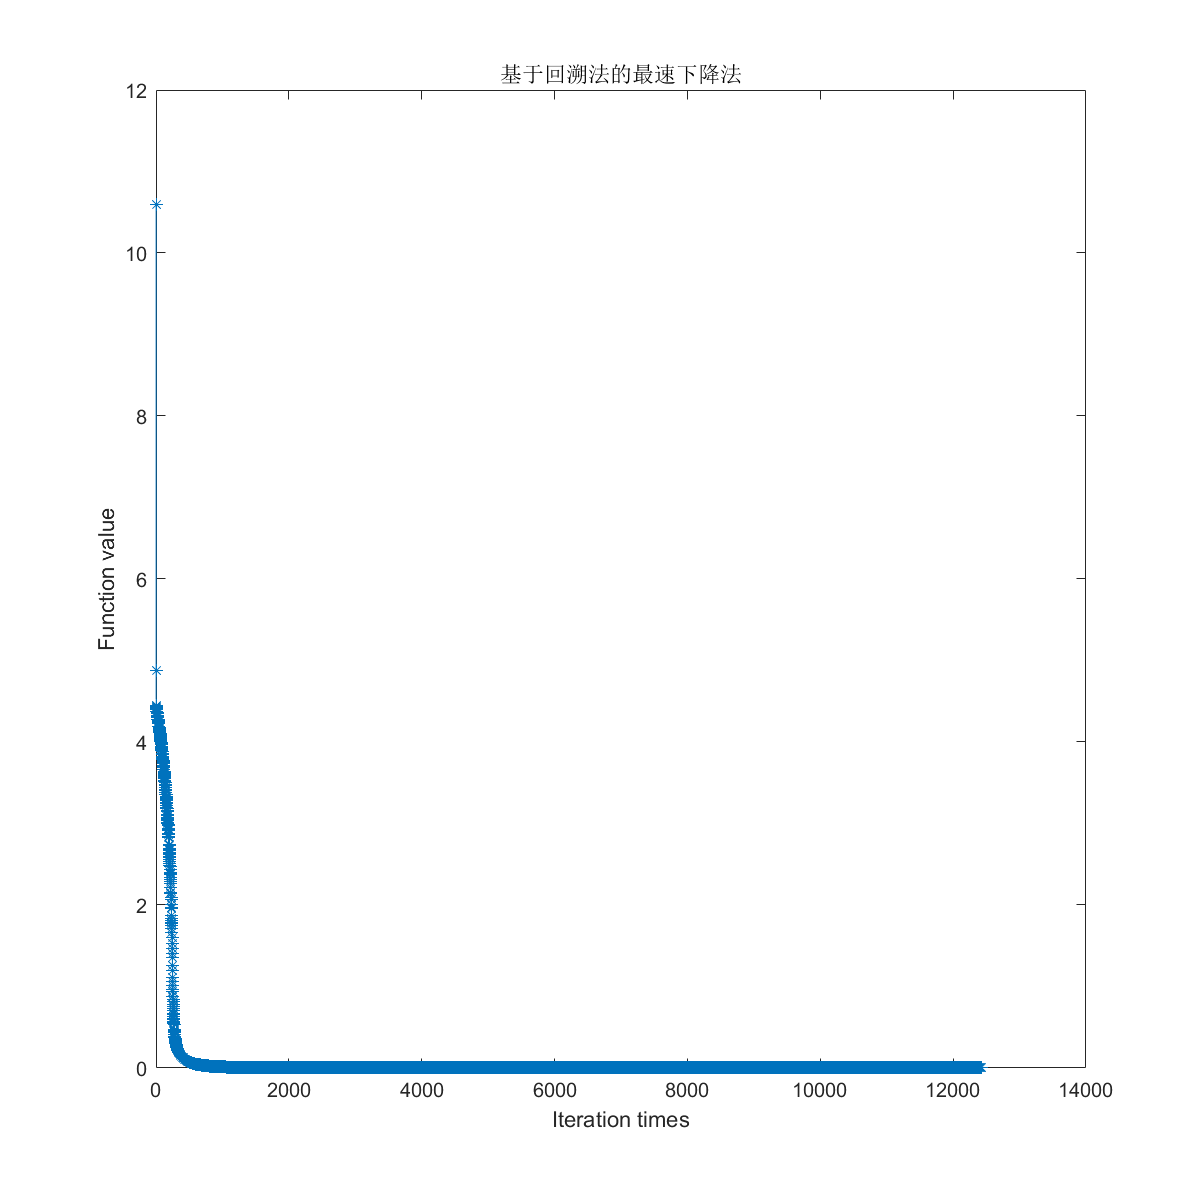

plot(1:1:count, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于回溯法的最速下降法')

x(:, end)

ans =     1.0000
    1.0000


fx(end)

ans = 5.0163e-11

clf;
clc;
x0 = [-1.2; 1.2];
% 基于回溯法的Newton迭代
tic
[x, fx, count] = Newton(@Rosenbrock, @BackTracking, x0, 100);
toc

时间已过 0.009253 秒。


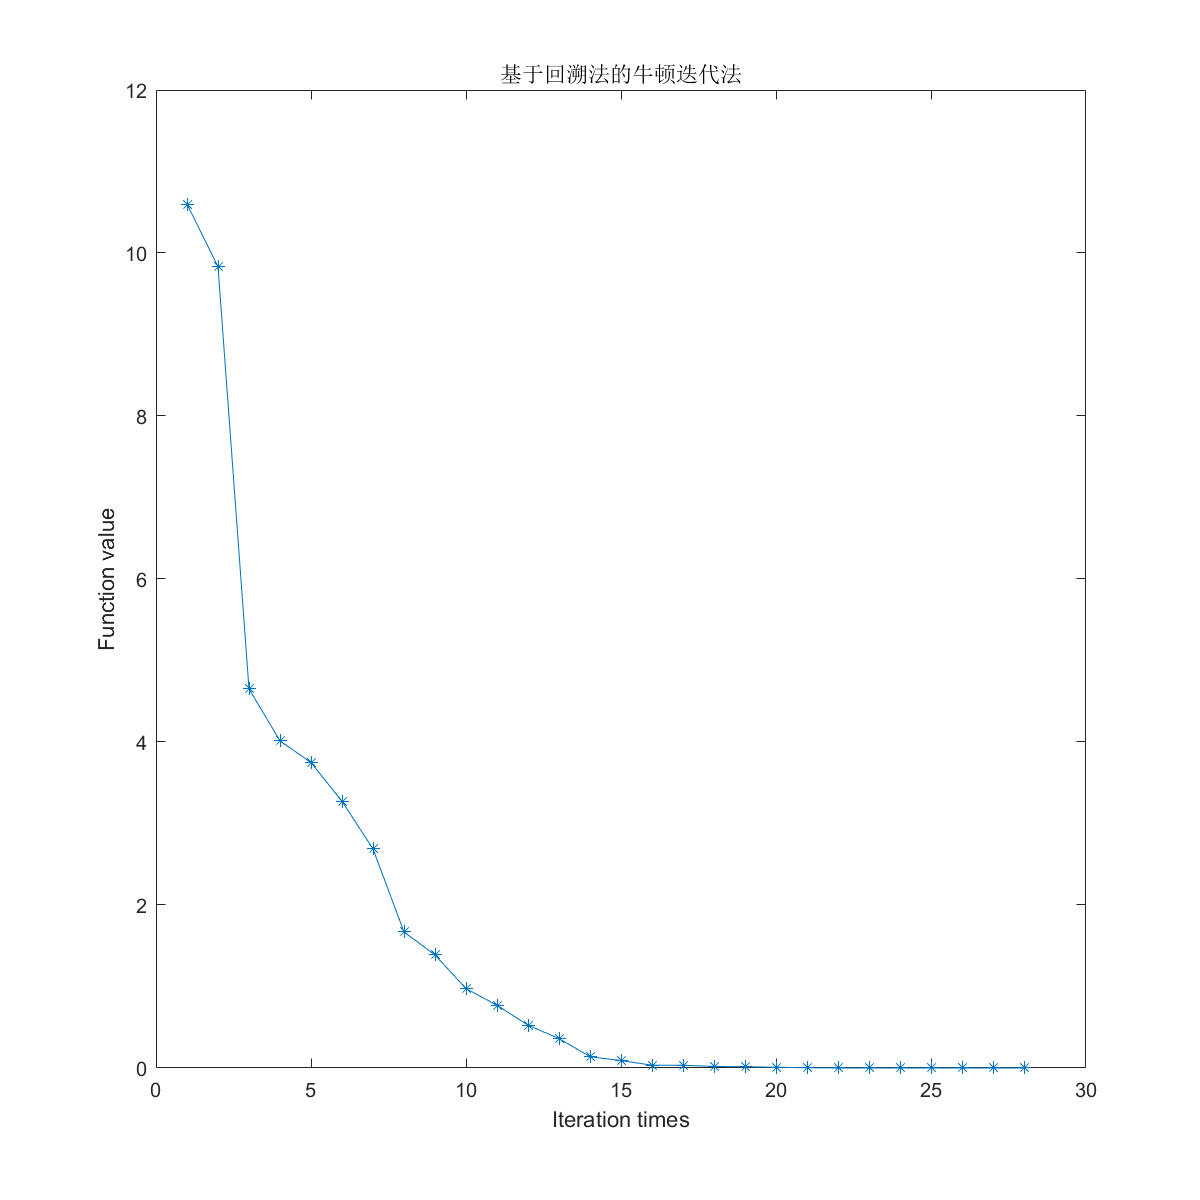

plot(1:1:count, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于回溯法的牛顿迭代法')

x(:, end)

ans =     1.0000
    1.0000


fx(end)

ans = 1.7810e-20

## 2. 编写函数实现基于Wolfe条件的Newton法，以Rosenbrock函数作为目标函数进行测试：

clf;
clc;
x0 = [-1.2; 1.2];
% 基于Wolfe条件的Newton迭代，参考书上算法3.5和3.6
tic
[x, fx, count] = Newton(@Rosenbrock, @Wolfe, x0, 100);
toc

时间已过 0.007797 秒。


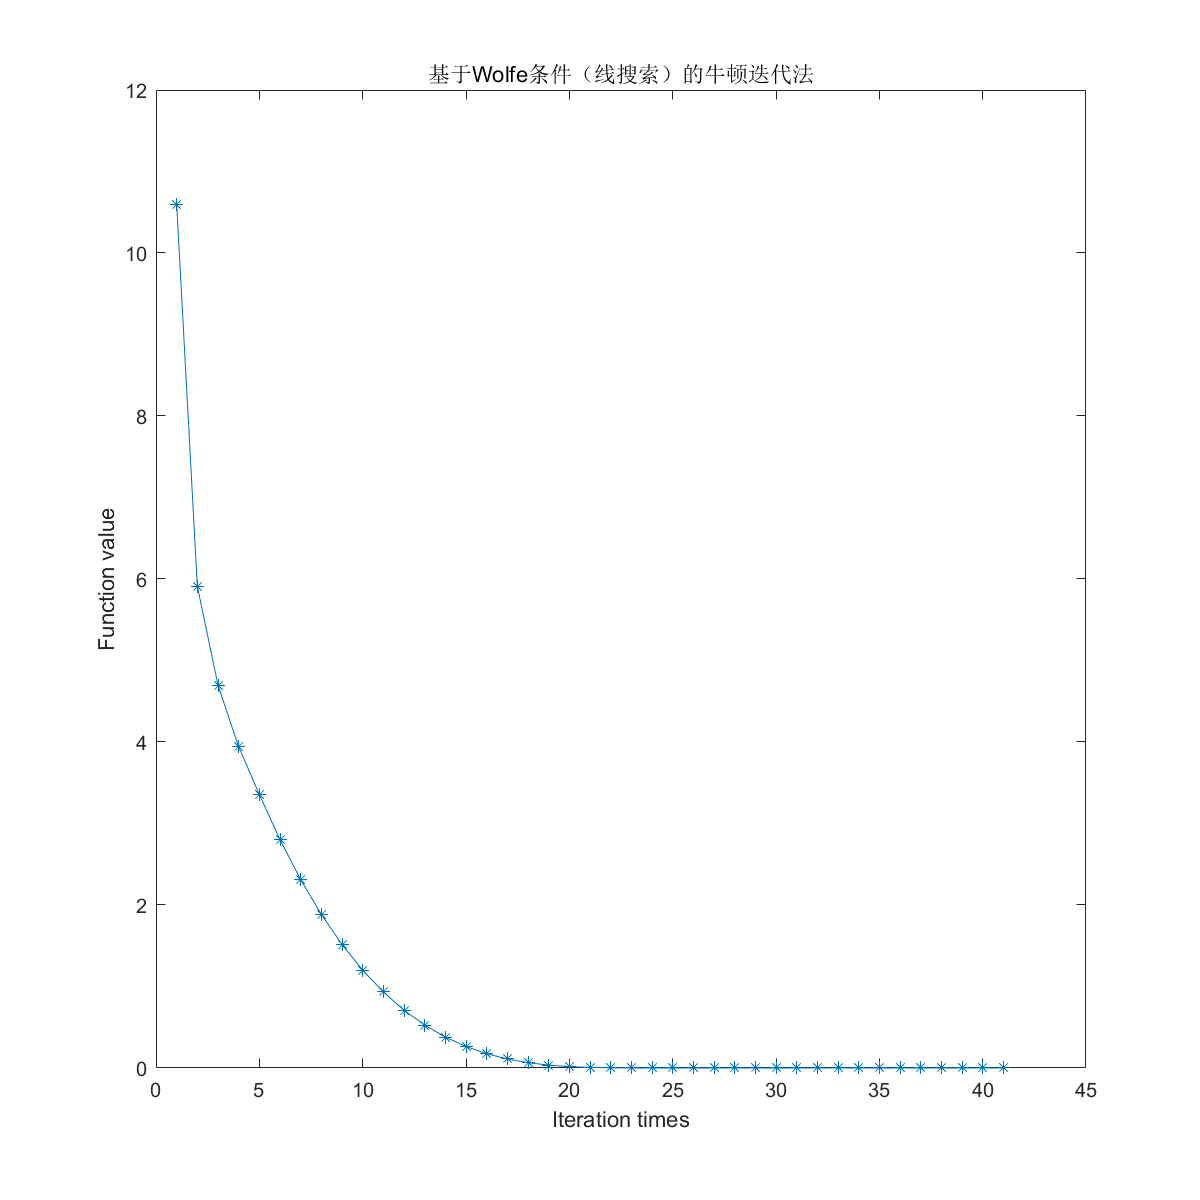

plot(1:1:count, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于Wolfe条件（线搜索）的牛顿迭代法');

x(:, end)

ans =     1.0000
    1.0000


fx(end)

ans = 7.0133e-16

clf;
clc;
x0 = [-1.2; 1.2];
tic
[x, fx, count] = SteepestDescent(@Rosenbrock, @Wolfe, x0, 1e5);
toc

时间已过 0.292075 秒。


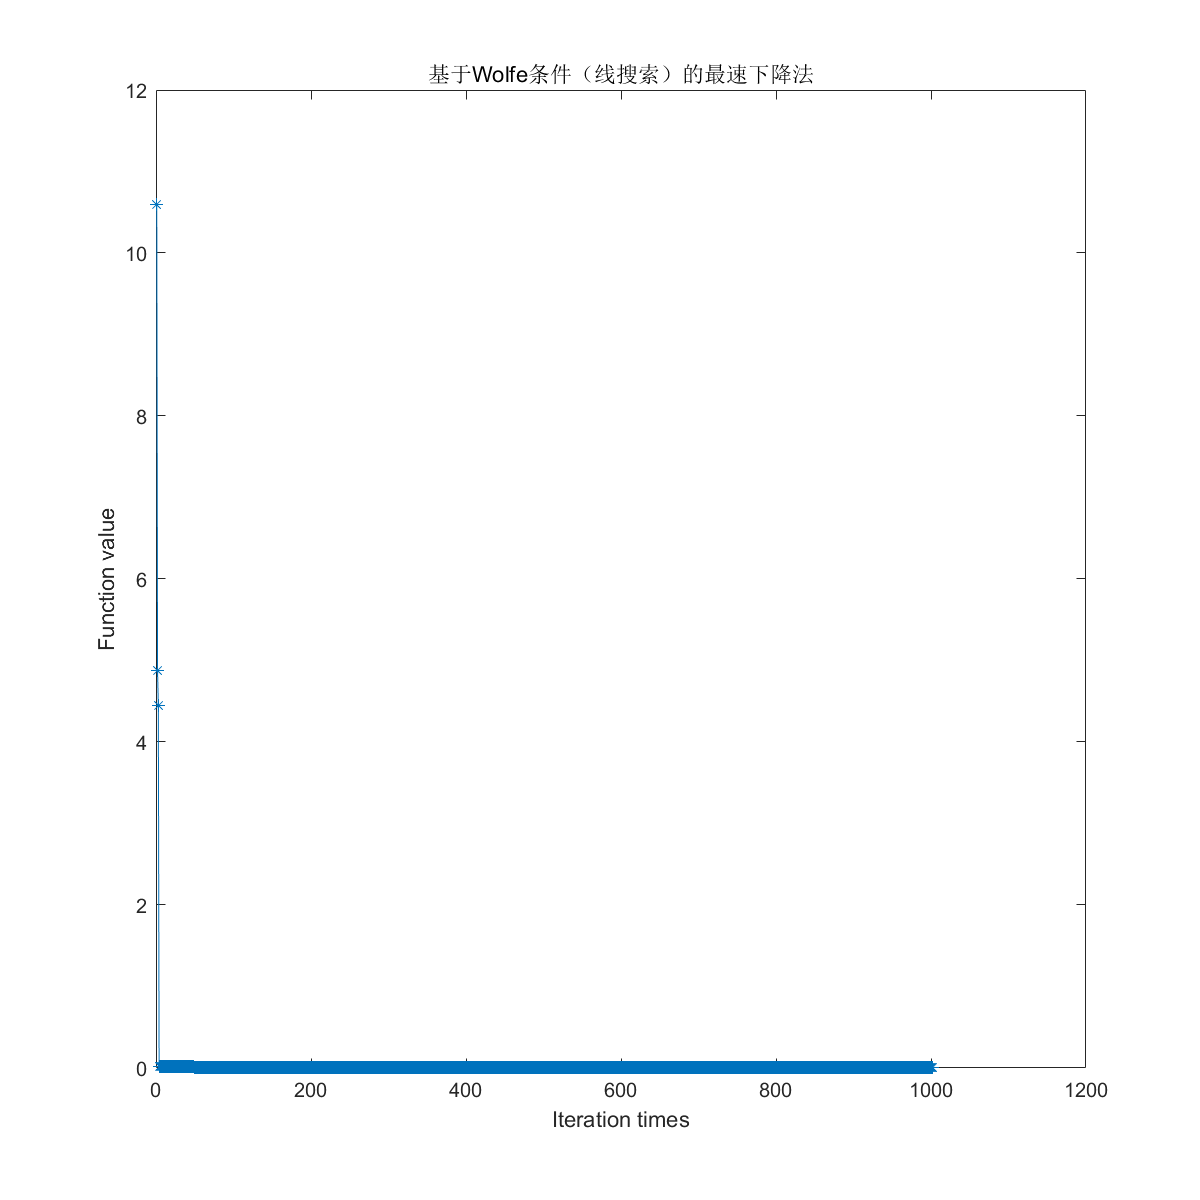

plot(1:1:count, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于Wolfe条件（线搜索）的最速下降法');

x(:, end)

ans =     1.0000
    1.0000


fx(end)

ans = 1.2047e-12

## 从上述结果可以看到，牛顿法比最速下降法收敛速度更快，效果更好。此外回溯法找步长比Wolfe条件找步长更快。

## 3. 添加最速下降法和牛顿法迭代过程中的轨迹可视化结果：

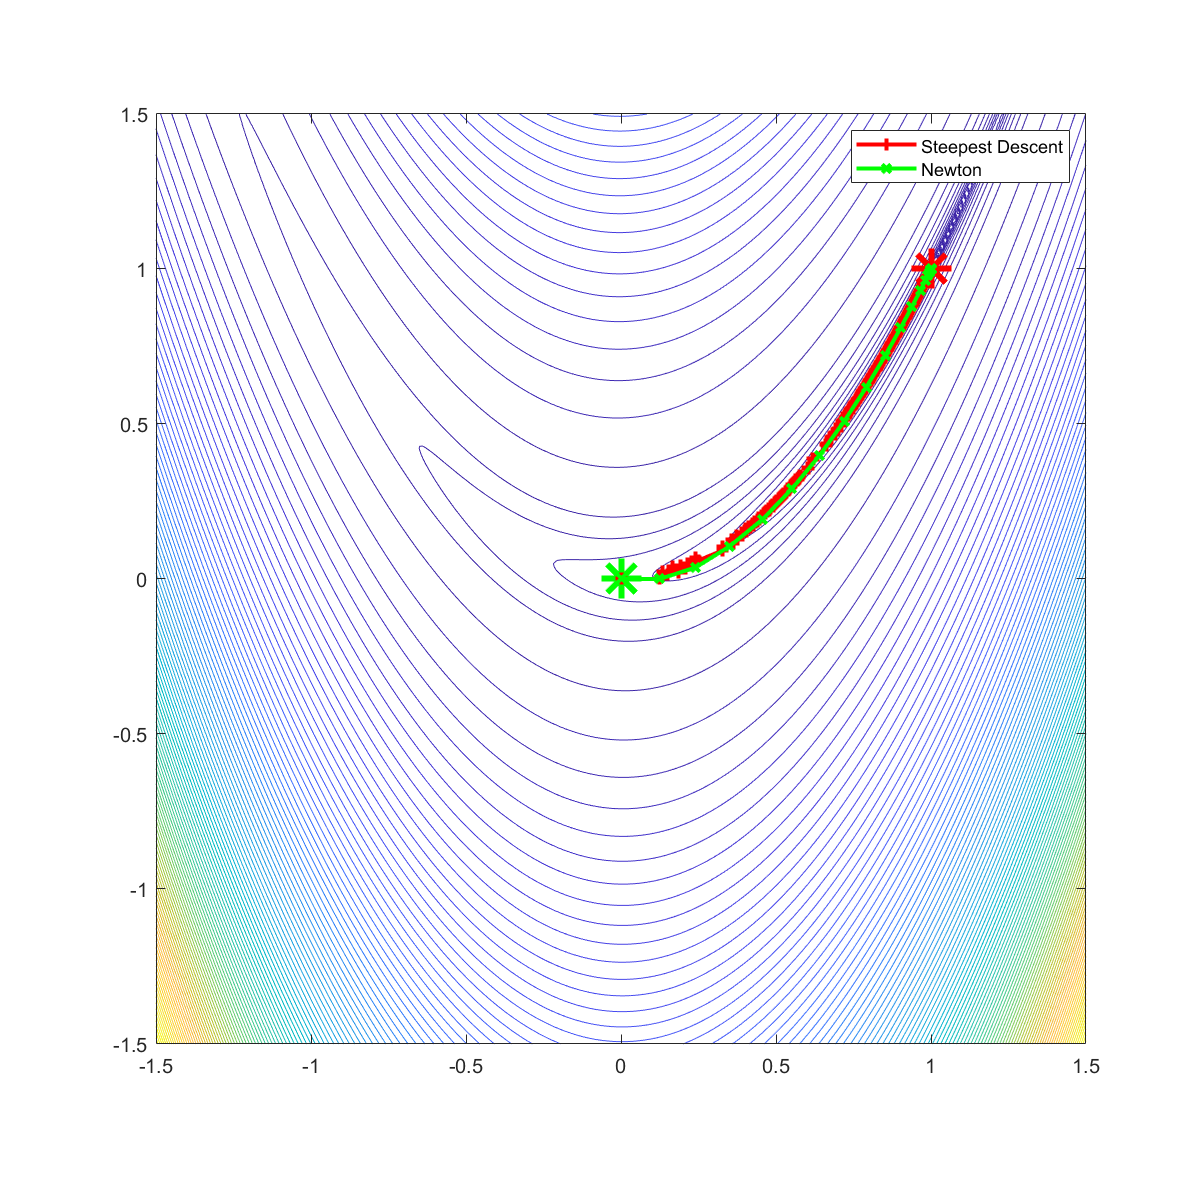

clc;
clf;
x = -1.5:0.01:1.5;
y = -1.5:0.01:1.5;
[X, Y] = meshgrid(x, y);
[w, h] = size(X);
vX = reshape(X, 1, w*h);
vY = reshape(Y, 1, w*h);
newX = [vX; vY];
vZ = zeros(size(vX));
for i=1:w*h
    [vZ(i), ~, ~] = Rosenbrock(newX(:, i));
end

figure();
set(gcf,'Position',[100 100 800 800]);
Z = reshape(vZ, w, h);
contour(X, Y, Z, 100);

v = logspace(-3, 0.7, 15);
hold on;
contour(X, Y, Z, v);
axis equal;

% Target
plot(1, 1, 'r*', 'MarkerSize', 20, 'LineWidth', 3);
% Start
plot(0, 0, 'g*', 'MarkerSize', 20, 'LineWidth', 3);
x0 = [0;0];

% Trajectory of Steepest Descent method
[x_SD, ~, ~] = SteepestDescent(@Rosenbrock, @Wolfe, x0, 1e4);
f1 = plot(x_SD(1,:), x_SD(2, :), 'r-+', 'LineWidth',2);

% Trajectory of Newton method
[x_Newton, ~, ~] = Newton(@Rosenbrock, @Wolfe, x0, 100);
f2 = plot(x_Newton(1, :), x_Newton(2, :), 'g-x', 'LineWidth',2);
legend([f1, f2],'Steepest Descent', 'Newton');

## 4. 基于Wolfe条件的回溯法

clf;
clc;
x0 = [-1.2; 1.2];
% 基于回溯法的Newton迭代
% 将终止条件替换为Wolfe条件
tic
[x, fx, count] = Newton(@Rosenbrock, @BackTracking_Wolfe, x0, 100);
toc

时间已过 0.011356 秒。


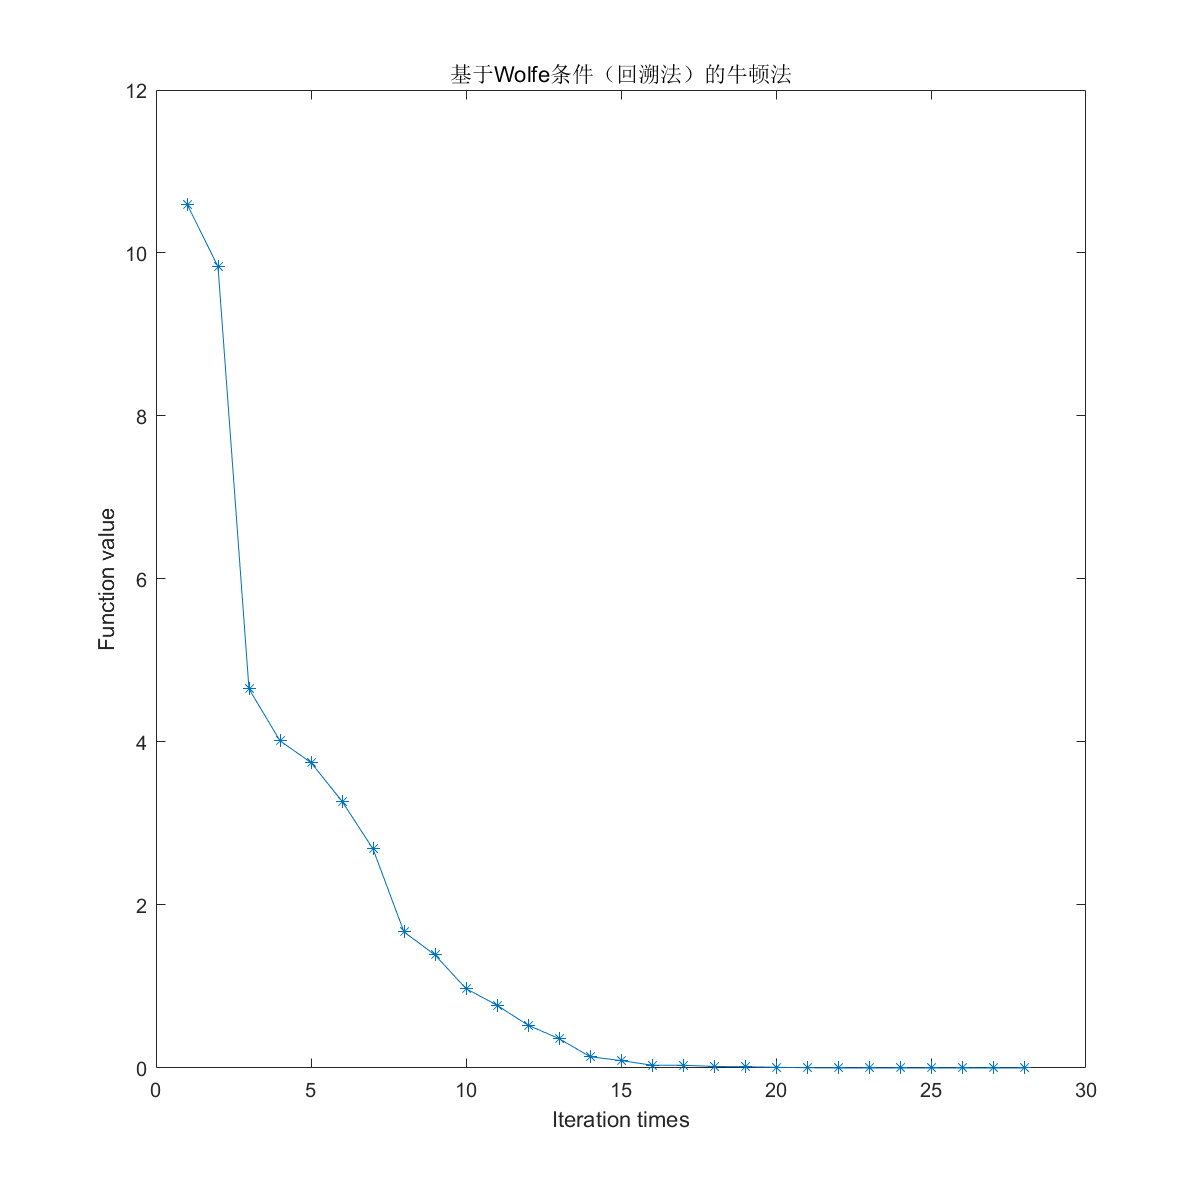

plot(1:1:count, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于Wolfe条件（回溯法）的牛顿法');

x(:, end)

ans =     1.0000
    1.0000


fx(end)

ans = 1.7810e-20

clf;
clc;
x0 = [-1.2; 1.2];
% 基于回溯法的最速下降法
% 将终止条件替换为Wolfe条件
tic
[x, fx, count] = SteepestDescent(@Rosenbrock, @BackTracking_Wolfe, x0, 1e5);
toc

时间已过 0.731775 秒。


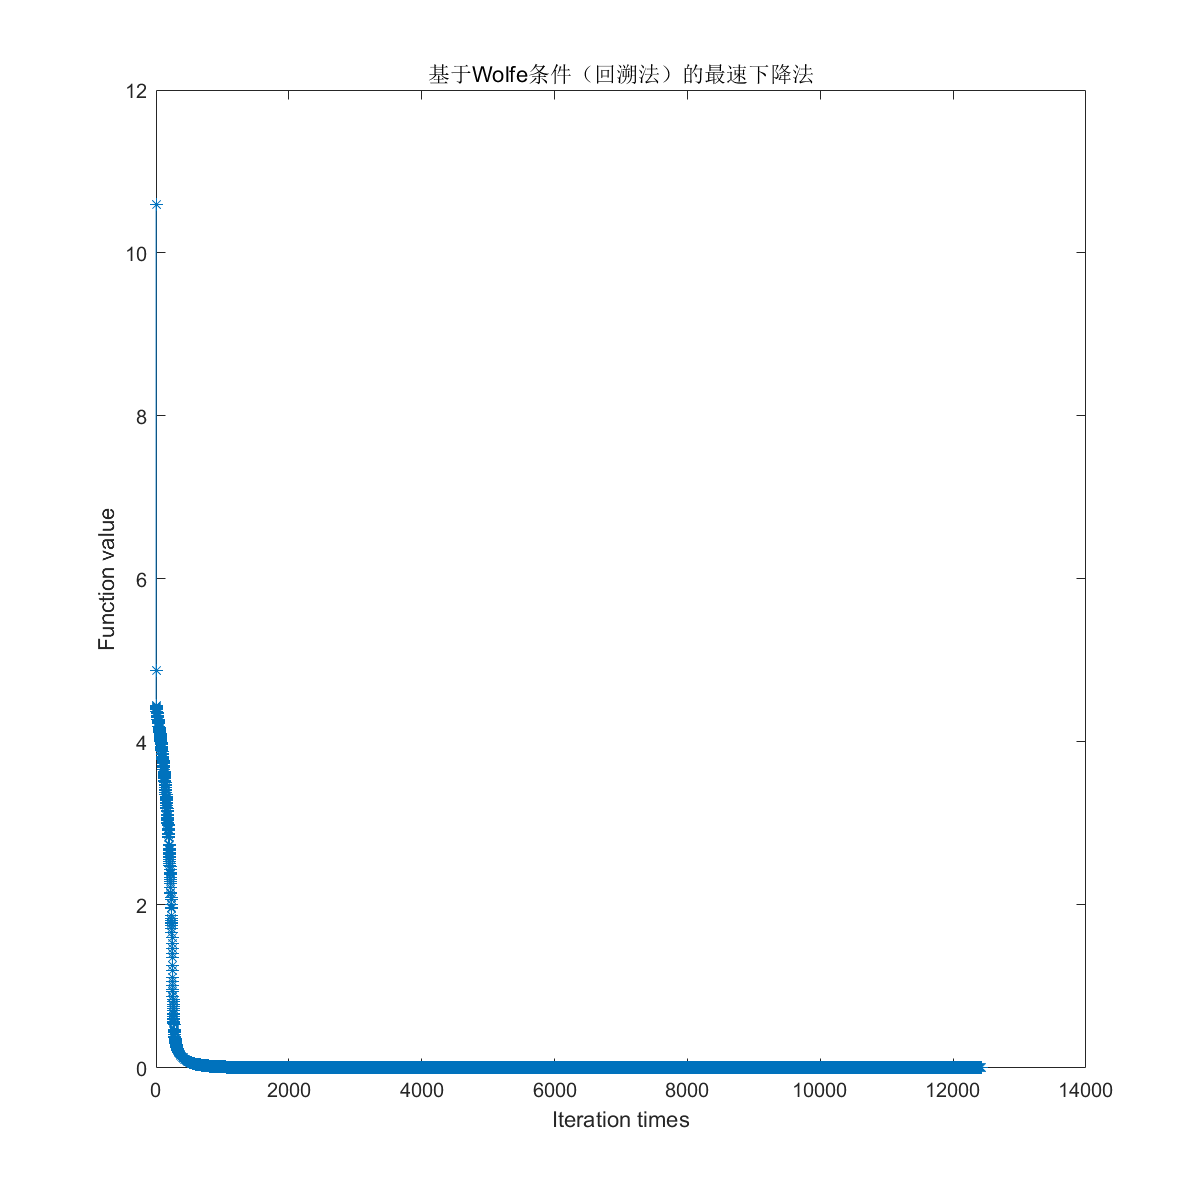

plot(1:1:count, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于Wolfe条件（回溯法）的最速下降法');

x(:, end)

ans =     1.0000
    1.0000


fx(end)

ans = 5.0163e-11

## 与MATLAB自带实现进行对比：

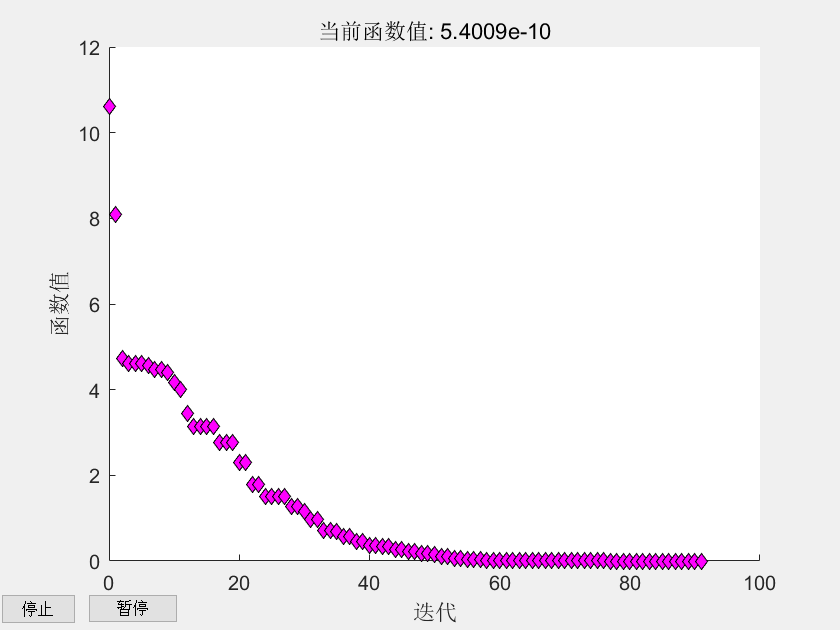

fun = @(x)100*(x(2) - x(1)^2)^2 + (1 - x(1))^2;
x0 = [-1.2,1.2];
options = optimset('PlotFcns',@optimplotfval);
[x, fval, ~, output]  = fminsearch(fun,x0, options);